# TEMPOmap cardiomyocytes 64Gene merge_spots

addpath('Z:/Documents/starmap_colab/Pipeline/');
addpath('Z:/Documents/starmap_colab/Code/matlab/');
addpath('Z:/Documents/starmap_colab/Code/matlab/myfunction/');

input_path = 'Z:\Data\Processed\2022-09-30-Rena-Cardiomyocyte64Gene\output\';

## Load TileConfiguration

current_well = 'Area_6'

current_well = 'Area_6'

rotation_degree = -90;

% merge dots 
stitch_file = fullfile(input_path,  '2022-10-07-rotation\rotated_seqDapi\', current_well, "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y', 'z'};
TileConfiguration.x = int32(fix(TileConfiguration.x));
TileConfiguration.y = int32(fix(TileConfiguration.y));
TileConfiguration.z = int32(fix(TileConfiguration.z));

head(TileConfiguration, 5)

ans = 5×4 table
    tile     x      y     z 
    ____    ____    __    __

    451        0     0     0
    462     1824    -2    -2
    473     3659     0    -2
    484     5491    -1    -2
    495     7329     0    -2



%% Clear temporary variables
clear opts

% Global offsets 
offset_x = abs(min(TileConfiguration.x));
offset_y = abs(min(TileConfiguration.y));
offset_z = abs(min(TileConfiguration.z));

TileConfiguration.x = TileConfiguration.x + offset_x + 1;
TileConfiguration.y = TileConfiguration.y + offset_y + 1;
TileConfiguration.z = TileConfiguration.z + offset_z + 1;

## Merge dots

% load stitched dapi image
dapi_file = fullfile(input_path, "2022-10-08-stitching/dapi/", append(current_well,'.tif'))

dapi_file = "Z:\Data\Processed\2022-09-30-Rena-Cardiomyocyte64Gene\output\2022-10-08-stitching\dapi\Area_6.tif"

% dapi_img = imread_big(dapi_file);
dapi_3d = imread_big(dapi_file);
dapi_max = max(dapi_3d, [], 3);

% create empty holders 
merged_points = int32([]);
merged_reads = {};
merged_region = [];

upd = textprogressbar(size(TileConfiguration,1), 'updatestep', 2);

Completed [                    ]   0% --:--:--

for r=1:size(TileConfiguration,1)
% for r=1:3
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("Position%03d", tile) 
    curr_dot_file = fullfile(input_path, "2022-10-05-spot-finding", curr_position_dir, "goodPoints_max3d.mat");
    if isfile(curr_dot_file)
        load(curr_dot_file); 
        
        %% a twist here: there are position folders that does not contain .mat file
        if ~isempty(tile_goodSpots)
             if rotation_degree == -90
                % rotate 90 c
                temp = tile_goodSpots;
                tile_goodSpots(:, 2) = temp(:, 1);
                tile_goodSpots(:, 1) = 2049 - temp(:, 2);
             end
            
            tile_goodSpots = int32(tile_goodSpots) + int32([x y z]);    
            % construct dots region
            current_min = min(tile_goodSpots, [], 1);
            current_max = max(tile_goodSpots, [], 1);
            if current_max(1) > size(dapi_max, 2)
                % fprintf("1")
                current_max(1) = size(dapi_max, 2);
                toKeep = tile_goodSpots(:, 1) <= current_max(1);
                tile_goodSpots = tile_goodSpots(toKeep, :);
                tile_goodReads = tile_goodReads(toKeep);
            
            else if current_max(2) > size(dapi_max, 1)
                    % fprintf("2")
                    current_max(2) = size(dapi_max, 1);   
                    toKeep = tile_goodSpots(:, 2) <= current_max(2);
                    tile_goodSpots = tile_goodSpots(toKeep, :);
                    tile_goodReads = tile_goodReads(toKeep);
                  
            end
            end
            current_region = zeros(size(dapi_max));
            current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
            % current_region(y+1:current_max(2), x+1:current_max(1)) = 1;
            
            % merge dots 
            if isempty(merged_region)
                merged_region = current_region;
            else
                current_overlap = merged_region & current_region;
                merged_region = merged_region | current_region;
                current_region = current_region - current_overlap; 
                
                temp_cell = num2cell(tile_goodSpots, 2); 
                current_lindex = cellfun(@(x) sub2ind([size(dapi_3d)], x(2), x(1)), temp_cell);
                current_logical = logical(current_region(current_lindex));
                tile_goodSpots = tile_goodSpots(current_logical, :);
                tile_goodReads = tile_goodReads(current_logical);
            end
            
            % save current 
            merged_points = [merged_points; tile_goodSpots]
            merged_reads = [merged_reads; tile_goodReads];
        end
    end
    upd(r);
end

curr_position_dir = "Position451"

merged_points = 6243×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position462"

merged_points = 10234×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [                    ]   2% 00:01:58

curr_position_dir = "Position473"

merged_points = 15858×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position484"

merged_points = 21691×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [                    ]   4% 00:02:04

curr_position_dir = "Position495"

merged_points = 26432×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position506"

merged_points = 31918×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=                   ]   6% 00:02:09

curr_position_dir = "Position517"

merged_points = 37146×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position528"

merged_points = 41761×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=                   ]   9% 00:02:08

curr_position_dir = "Position450"

merged_points = 46933×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position461"

merged_points = 51657×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==                  ]  11% 00:02:04

curr_position_dir = "Position472"

merged_points = 56899×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position483"

merged_points = 61191×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==                  ]  13% 00:02:01

curr_position_dir = "Position494"

merged_points = 65931×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position505"

merged_points = 71498×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [===                 ]  15% 00:01:59

curr_position_dir = "Position516"

merged_points = 77942×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position527"

merged_points = 83365×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [===                 ]  18% 00:01:55

curr_position_dir = "Position449"

merged_points = 87780×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position460"

merged_points = 93635×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [====                ]  20% 00:01:53

curr_position_dir = "Position471"

merged_points = 98477×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position482"

merged_points = 103382×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [====                ]  22% 00:01:49

curr_position_dir = "Position493"

merged_points = 107919×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position504"

merged_points = 112154×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=====               ]  25% 00:01:47

curr_position_dir = "Position515"

merged_points = 116305×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position526"

merged_points = 122327×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=====               ]  27% 00:01:43

curr_position_dir = "Position448"

merged_points = 129299×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position459"

merged_points = 135142×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=====               ]  29% 00:01:40

curr_position_dir = "Position470"

merged_points = 139609×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position481"

merged_points = 142651×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [======              ]  31% 00:01:37

curr_position_dir = "Position492"

merged_points = 147364×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position503"

merged_points = 151852×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [======              ]  34% 00:01:35

curr_position_dir = "Position514"

merged_points = 156229×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position525"

merged_points = 162203×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=======             ]  36% 00:01:31

curr_position_dir = "Position447"

merged_points = 168399×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position458"

merged_points = 172971×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=======             ]  38% 00:01:28

curr_position_dir = "Position469"

merged_points = 177484×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position480"

merged_points = 182048×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [========            ]  40% 00:01:25

curr_position_dir = "Position491"

merged_points = 187335×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position502"

merged_points = 193162×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [========            ]  43% 00:01:22

curr_position_dir = "Position513"

merged_points = 197304×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position524"

merged_points = 201726×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=========           ]  45% 00:01:18

curr_position_dir = "Position446"

merged_points = 208286×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position457"

merged_points = 213983×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=========           ]  47% 00:01:15

curr_position_dir = "Position468"

merged_points = 220051×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position479"

merged_points = 225036×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==========          ]  50% 00:01:12

curr_position_dir = "Position490"

merged_points = 229001×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position501"

merged_points = 234227×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==========          ]  52% 00:01:09

curr_position_dir = "Position512"

merged_points = 238918×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position523"

merged_points = 243855×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==========          ]  54% 00:01:05

curr_position_dir = "Position445"

merged_points = 249684×3 int32 matrix
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position456"

merged_points = 255253×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [===========         ]  56% 00:01:02

curr_position_dir = "Position467"

merged_points = 259749×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position478"

merged_points = 263864×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [===========         ]  59% 00:00:59

curr_position_dir = "Position489"

merged_points = 268873×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position500"

merged_points = 273386×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [============        ]  61% 00:00:56

curr_position_dir = "Position511"

merged_points = 278603×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position522"

merged_points = 282763×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [============        ]  63% 00:00:52

curr_position_dir = "Position444"

merged_points = 287912×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position455"

merged_points = 291903×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=============       ]  65% 00:00:49

curr_position_dir = "Position466"

merged_points = 298232×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position477"

merged_points = 302969×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=============       ]  68% 00:00:46

curr_position_dir = "Position488"

merged_points = 308261×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position499"

merged_points = 312710×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==============      ]  70% 00:00:43

curr_position_dir = "Position510"

merged_points = 318125×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position521"

merged_points = 322941×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==============      ]  72% 00:00:39

curr_position_dir = "Position443"

merged_points = 327711×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position454"

merged_points = 334230×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [===============     ]  75% 00:00:36

curr_position_dir = "Position465"

merged_points = 339570×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position476"

merged_points = 345167×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [===============     ]  77% 00:00:33

curr_position_dir = "Position487"

merged_points = 349998×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position498"

merged_points = 355598×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [===============     ]  79% 00:00:29

curr_position_dir = "Position509"

merged_points = 360357×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position520"

merged_points = 365403×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [================    ]  81% 00:00:26

curr_position_dir = "Position442"

merged_points = 370463×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position453"

merged_points = 376467×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [================    ]  84% 00:00:23

curr_position_dir = "Position464"

merged_points = 381901×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position475"

merged_points = 387153×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=================   ]  86% 00:00:20

curr_position_dir = "Position486"

merged_points = 392584×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position497"

merged_points = 397470×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=================   ]  88% 00:00:16

curr_position_dir = "Position508"

merged_points = 402247×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position519"

merged_points = 408059×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==================  ]  90% 00:00:13

curr_position_dir = "Position441"

merged_points = 413066×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position452"

merged_points = 418602×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [==================  ]  93% 00:00:10

curr_position_dir = "Position463"

merged_points = 423743×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position474"

merged_points = 428763×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=================== ]  95% 00:00:07

curr_position_dir = "Position485"

merged_points = 434098×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position496"

merged_points = 440168×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [=================== ]  97% 00:00:03

curr_position_dir = "Position507"

merged_points = 446217×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


curr_position_dir = "Position518"

merged_points = 450801×3
   1378     73     10
   1374     77     10
   1424    331     10
   1157    352     10
   1111    496     10
   1688    641     10
   1654    651     10
   1316    676     10
   1050    676     10
   1047    683     10


Completed [====================] Done. [144 seconds]


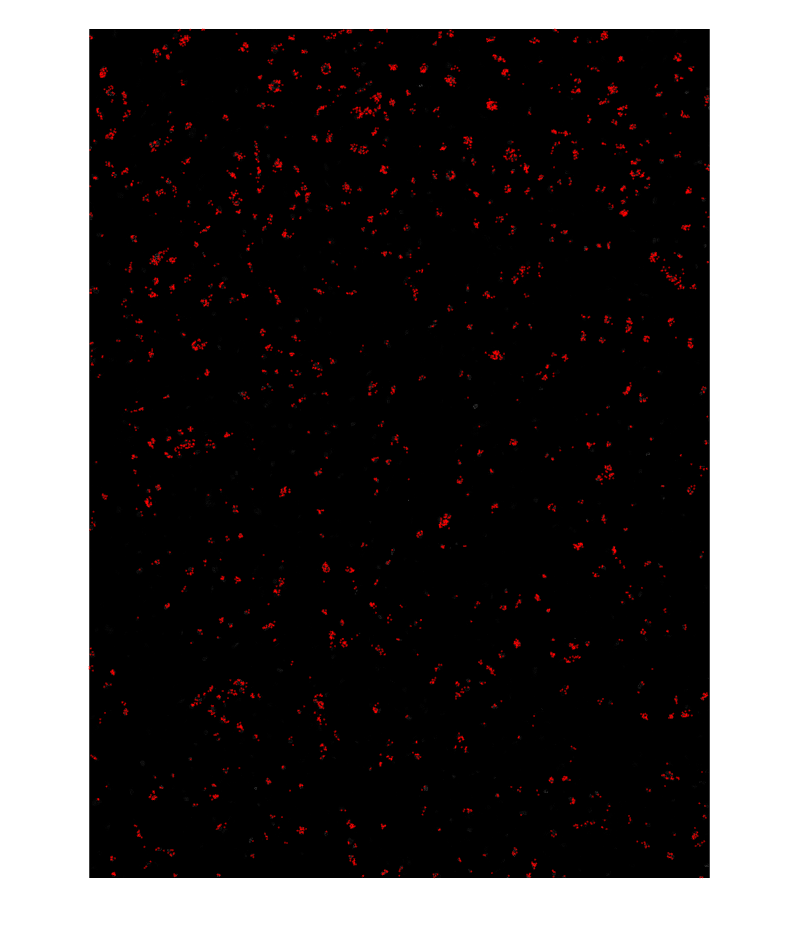


merged_points(:,1) = merged_points(:,1) - 1;
merged_points(:,2) = merged_points(:,2) - 1;
merged_points(:,3) = merged_points(:,3) - 1;

z = 20;
plot_centroids(merged_points(merged_points(:, 3) == z, :), dapi_3d(:,:,z), 1)

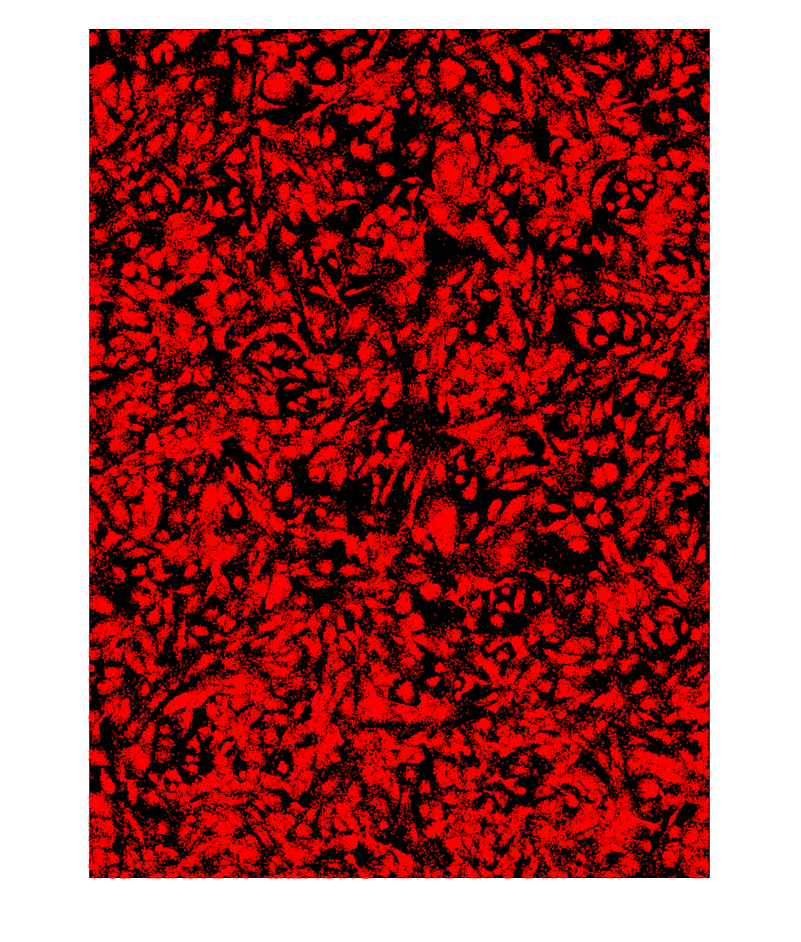


plot_centroids(merged_points, dapi_max, 1)

## output

spot_out_path = fullfile(input_path, '2022-10-15-merged-points', current_well);
if ~exist(spot_out_path, 'dir')
    mkdir(spot_out_path)
end
save(fullfile(input_path, '2022-10-15-merged-points', current_well, 'merged_goodPoints.mat'), "merged_points", "merged_reads");